% This program extratcts of the data from line printing of gelatin.
% 
% Material is 4.76% w/w gelatin
% Inner diameter of cylinder and syringe are 16 and 22.5 mm, repectively.
% Printing speed is 2 mm/s.
% Layer height is 800 microns.
% Printing temperature is 25 degreeC.
% 
% image_raw    is the raw image of the printed result.
% image_crop   is the rotated and croped image of the printed result.
% mm_per_pixel is unit conversion ratio in mm/pixel.
% edge         is detected edge pixels.
% linewidth    is determined linewidth values.

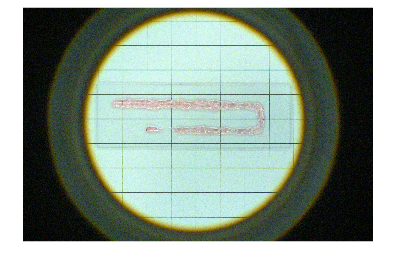

feedrate = '300'; % feedrate of cylinder in micron/s (available feedrate values: 300 and 400)

data_filename = ['line_dataset_f' feedrate '.mat'];
load(data_filename)

figure
imshow(image_raw)

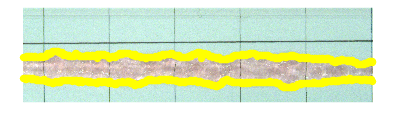


figure
imshow(image_crop)
hold on
hold on
plot(1:size(image_crop,2),edge(:,1),'.','Color',[1 1 0],'MarkerSize',12)
hold on
plot(1:size(image_crop,2),edge(:,2),'.','Color',[1 1 0],'MarkerSize',12)

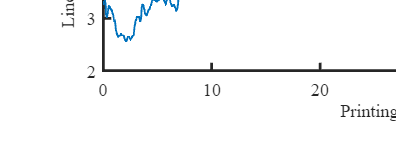


figure
fig = gcf;
fig.Units = 'centimeters';
fig.Position = [10 5 15.5 5.8];

color = colororder('gem');

plot([1:size(image_crop,2)]*mm_per_pixel,linewidth,'-','LineWidth',1);

ax = gca;
ax.Units = 'centimeters';
ax.Position = [2 1.5 12.5 4];
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.LineWidth = 1.5;
ax.Box = 'on';
xlim([0 60])
xticks(0:10:60)
ylim([floor(min(linewidth)/2)*2 ceil(max(linewidth)/2)*2])
yticks(linspace(floor(min(linewidth)/2)*2,ceil(max(linewidth)/2)*2,5))

xlabel('\fontname{Times New Roman}\rmPrinting distance \rm(mm)','FontSize',10)
ylabel('\fontname{Times New Roman}\rmLinewidth (mm)','FontSize',10)